# Joukowski transformation 

The Joukowski transformation is a conformal mapping function that will allow us to transform a circle into a airfoil profile. 

We create a unit circle in the $\zeta$- plane and transform it using the Joukowski transformation: $z=f_{\textrm{Joukowski}} \left(\zeta \right)=\zeta +\frac{a^2 }{\zeta }$ into the $z$-plane:

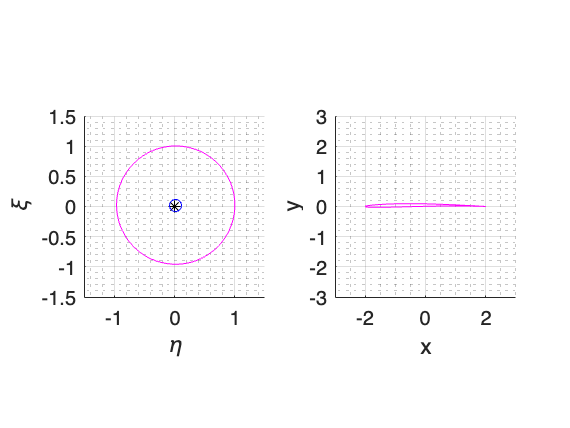

clear all
close all

% play with the origin of the circle in the \zeta-plane
ETAorigin = 0.02; 
XIorigin = 0.0231; 

ZETAorigin=ETAorigin+1i*XIorigin;
R=abs(ZETAorigin-1);
R0=abs(ZETAorigin);
delta=pi-angle(ZETAorigin);

% the coordinates of the circle:
ZETAcircle = R*exp(1i*linspace(0,2*pi,101))+ R0 * (-cos(delta)+1i*sin(delta));

% we define the Joukowski transform:
f = @(zeta,a) zeta + a^2./zeta; 

% and look at the result for a=1:
figure, 
subplot(1,2,1), hold all
plot(complex(0),'k*') % this is (0,0)
plot(complex(ZETAorigin),'bo') % this is the center of the circle 
plot(ZETAcircle,'m')
axis equal tight, axis([-1.5,1.5,-1.5,1.5]) 
grid on, grid minor
xlabel('\eta'), ylabel('\xi')
%
subplot(1,2,2), hold all
plot(f(ZETAcircle,1),'m')
view(2), axis equal tight, axis([-3,3,-3,3]) 
grid on, grid minor
xlabel('x'), ylabel('y') 